#### *Preamble*

close all
clearvars
clc

## VARIABLES

Fluid = "127";             % Select fliud
Metal = "18";             % Select metal      
WICK_TYPE = "sintered";         % Select Wick Type

## HEAT PIPE PROPERTIES 

HP_Length = 500;         % Heat Pipe Length, mm
COND_Length = 100;       % Condenser Length, mm
EVAP_Length = 100;       % Evaporator Length, mm
HP_Angle = 0;          % Operating Angle, °
OP_Temp = 100;           % Operationg Temeprature, °C
HP_Diameter = 25.4;       % Heat pipe diameter, mm
T_WALL = 1;            % Wall Thickness, mm
OPRATING_POWER = 150;    % Nominal operating power for dT estimates, W

## WICK PROPERTIES 

### *Mesh*

Mesh_material = "PhosB";     % Select Wick Material
N_WRAPS = 8;           % Number of Wraps, #
MESH_NUMBER = 200;       % Mesh Number, gaps p/ inch
D_WIRE = 0.0000625;            % Wire diamter, m
WICK_K = 50;            % Wick Thermal Conductivity, W/mK - Phosphorus Bronze = 386.4

### *Sinter*

SINTER_D = 0.1;          % Sinter Diameter, mm
MAND = 0;              % Mandrel Diameter, mm (set as 0 for optimal mandrel diameter)

## OTHER PROPERTIES

Contact_Angle = 0;     % Contact angle (deg) between fluid and metal (for ideal case put 0)
GRAVITY = 9.81;           % Acceleration due to gravity, m/s2
sf = 2;                % Wall thickness safety factor
Rn = 6e-8;                % Nucleation Radius Value, m

***Mesh - advanced***

gap_mult = 1;          % Gap multiplier for mesh wicks, - ;This is used to estimate the wick thichness taking into account the space between mesh layers. The multipliyer signifies a value that the wick thickness with no gaps is multiplied by to estimate the thickness with gaps. I've used a multiplier of 2.5 in the past to better correlate to mesh wick experimental results, but it is something that needs more investigation and should be used with caustion.  

*RUN CODE*

A_1_1_0a_DATA_EXTRACTION

Tmin = 0

Tmax = 374

B_1_1_0a_VARIABLE_DEFINITION

Min_wall_thickness_mm = -2.2949e-05

Optimal_mandrel_diameter_mm = 3.3500

MAND = 3.3500

Fill_Volume_cc = 107.1658

Fill_Mass_g = 102.4088

Maximum_Capilary_Rise_m = 0.7267

WICK_TYPE = "sintered"

NAME_FLUID = "WATER"

NAME_METAL = "Cu"

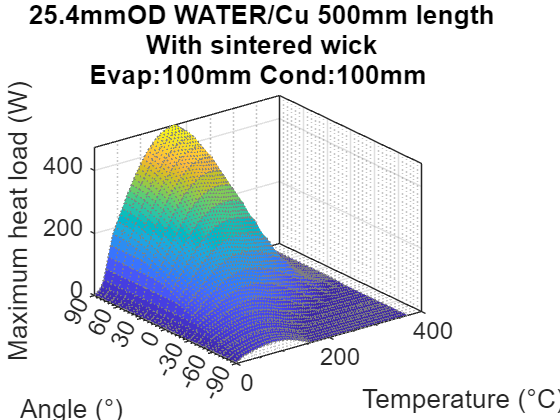

C_1_1_0a_CALCULATIONS
D_1_1_0a_dT_calc
G1_1_1_0a_Graph_1       % 3D plot

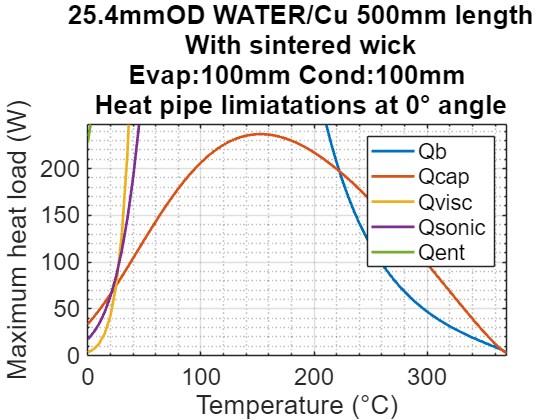

G2_1_1_0a_Graph_2       % All limits 

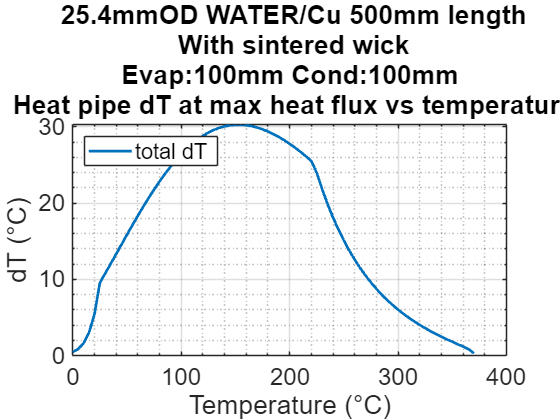

G3_1_1_0a_Graph_3       % dT 

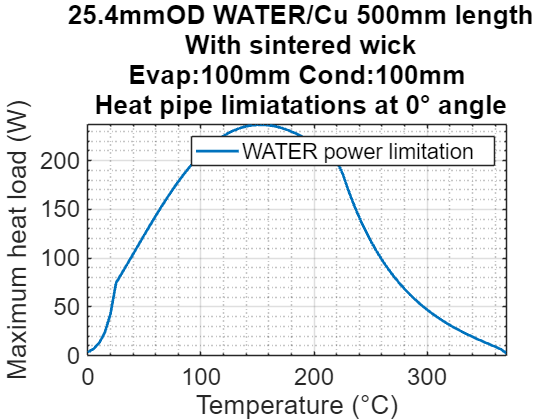

G4_1_1_0a_Graph_4       % Performance curve  

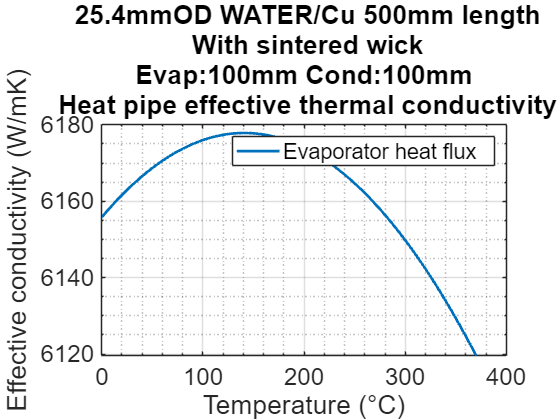

G5_1_1_0a_Graph_5       % Effective K

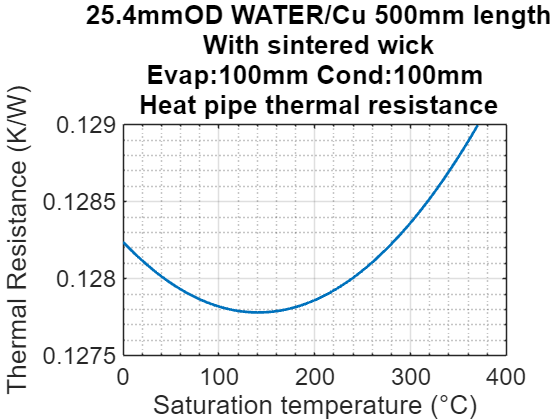

G6_1_1_0a_Graph_6       % Thermal resistance

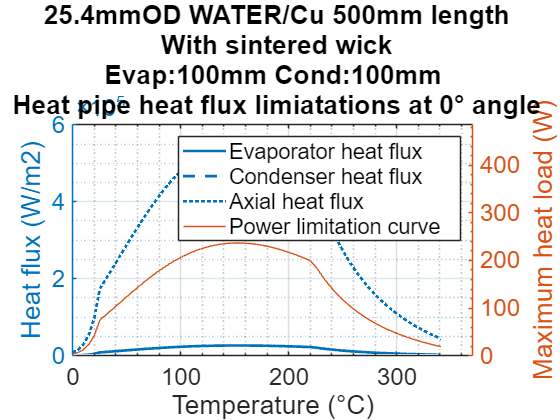

G7_1_1_0a_Graph_7       % Heat fluxes

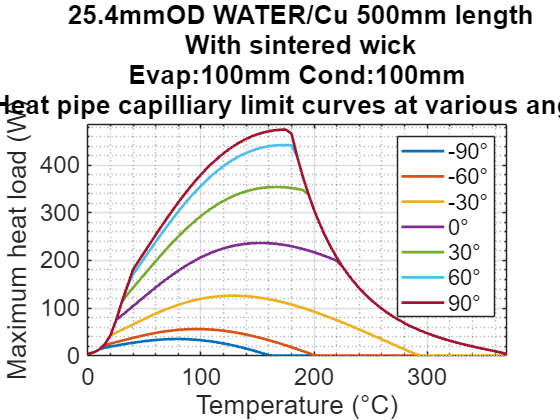

G8_1_1_0a_Graph_8       % Angle comparison

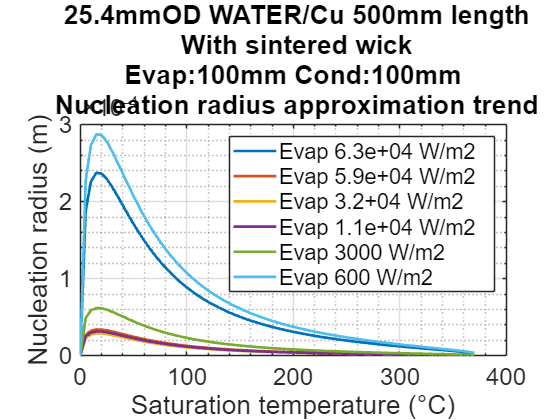

G9_1_1_0a_Graph_9       % Nucleation radius

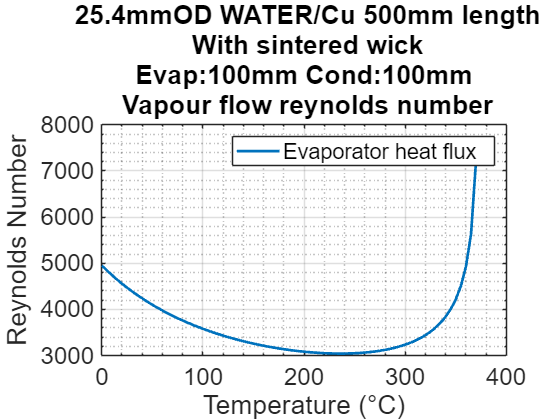

G10_1_1_0a_Graph_10     % Reynolds

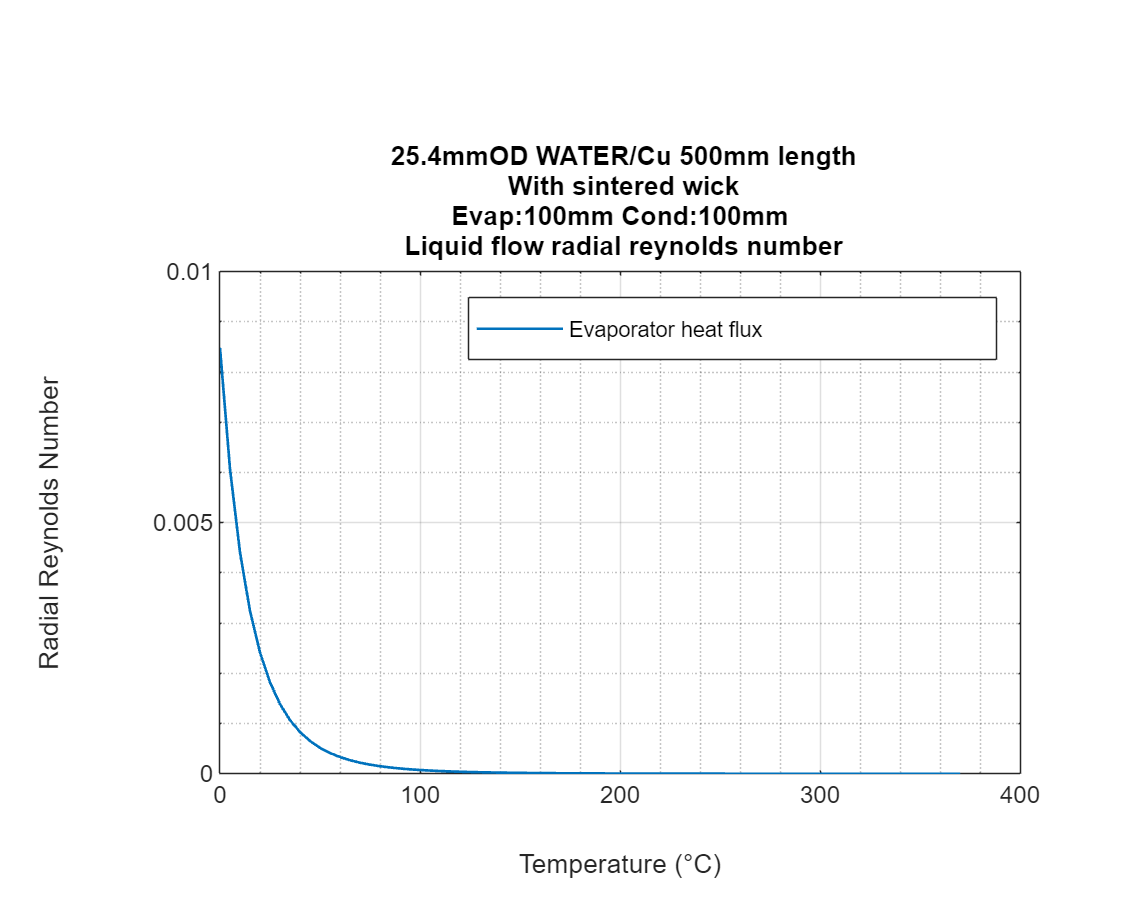

G11_1_1_0a_Graph_11     % Radial reynolds

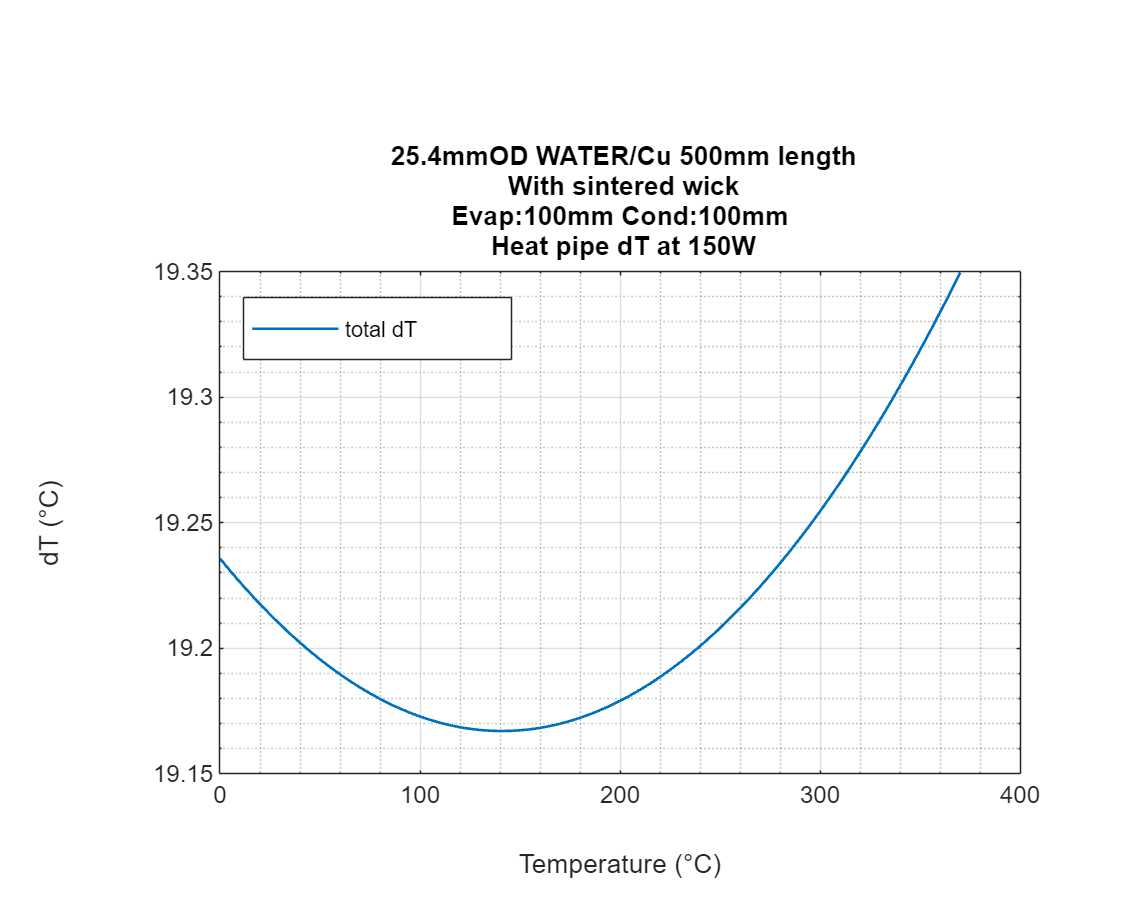

G12_1_1_0a_Graph_12     % dT at fixed operating power

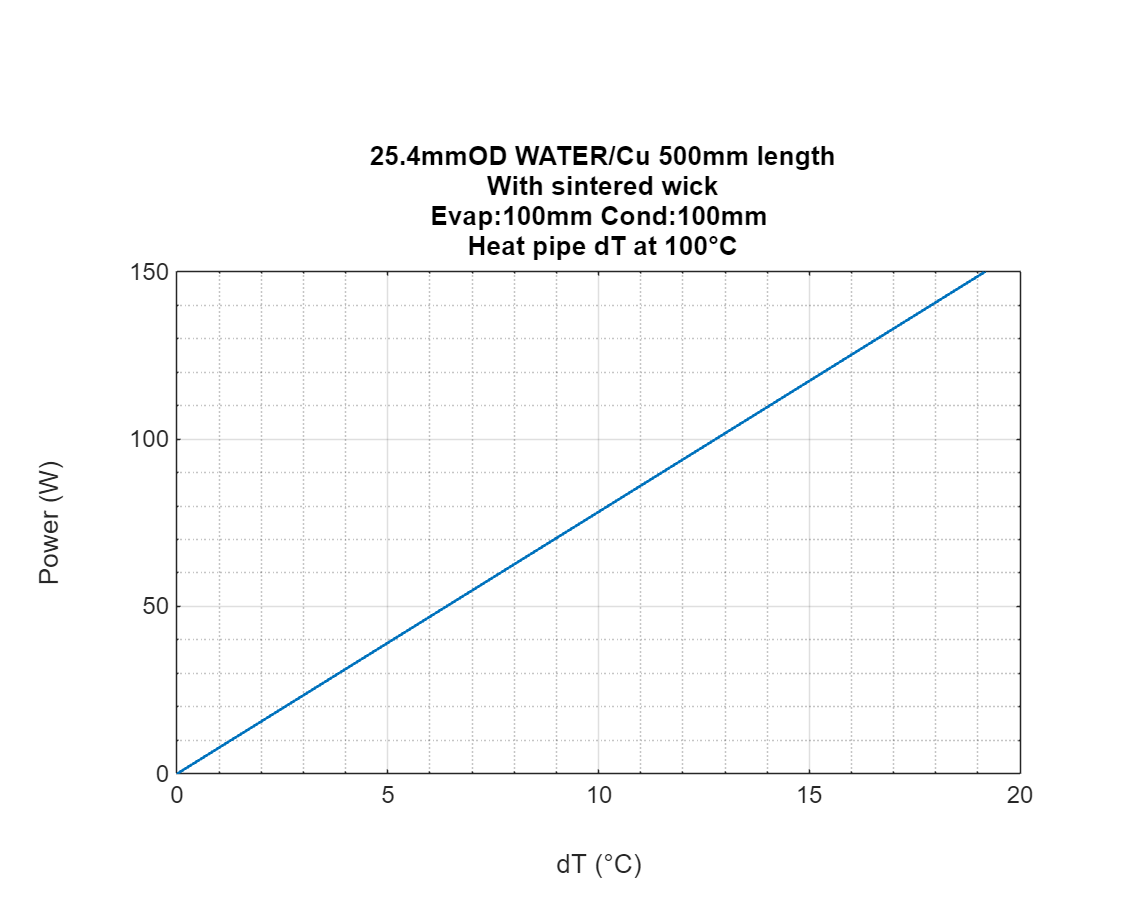

G13_1_1_0a_Graph_13     % dT at fixed temperature 

***Compare Fluids***

Fluid1 = "127";            % Select fliud
Fluid2 = "346";            % Select fliud
Fluid3 = "171";            % Select fliud
Fluid4 = "0";            % Select fliud
Fluid5 = "0";            % Select fliud
Fluid6 = "0";            % Select fliud
Fluid7 = "0";            % Select fliud
Fluid8 = "0";            % Select fliud
Fluid9 = "0";            % Select fliud
Fluid10 = "0";           % Select fliud

#### *OUTPUTS - COMPARATIVE*

WICK_TYPE = "sintered"

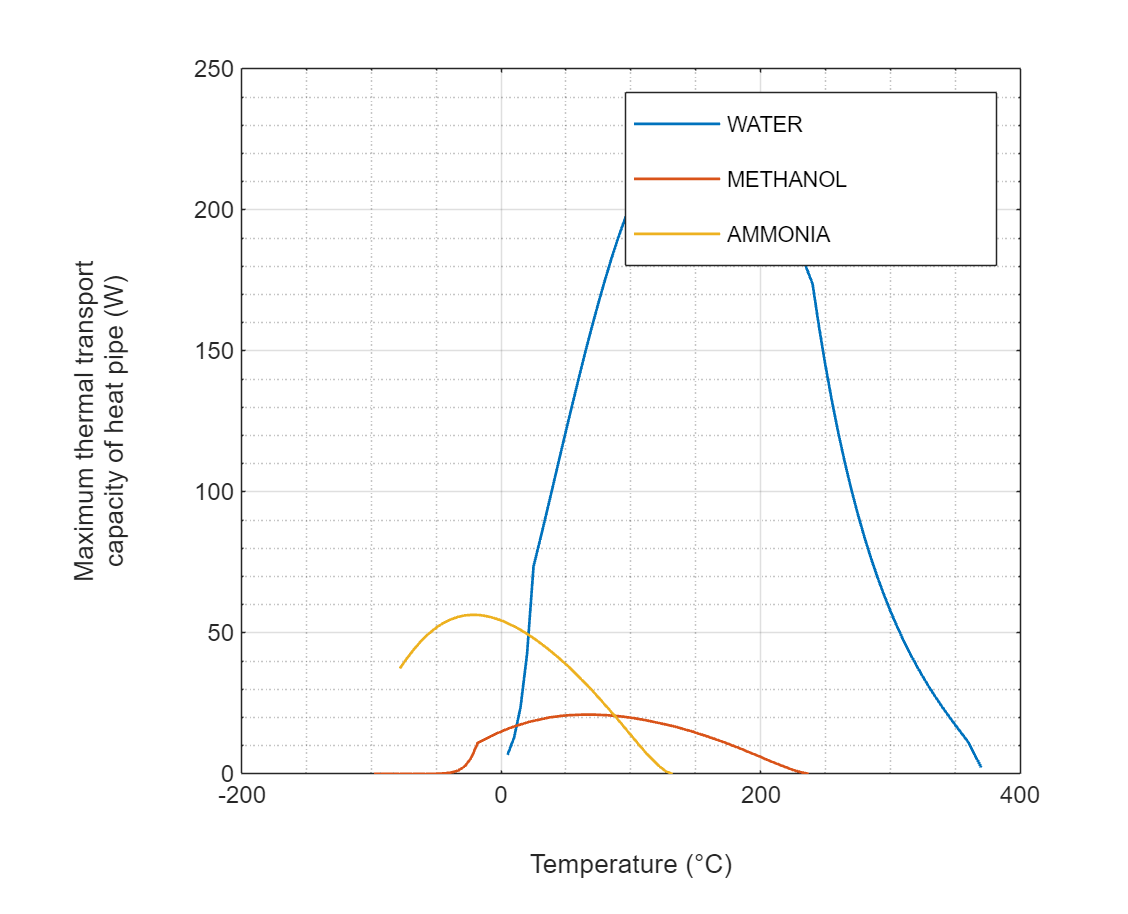

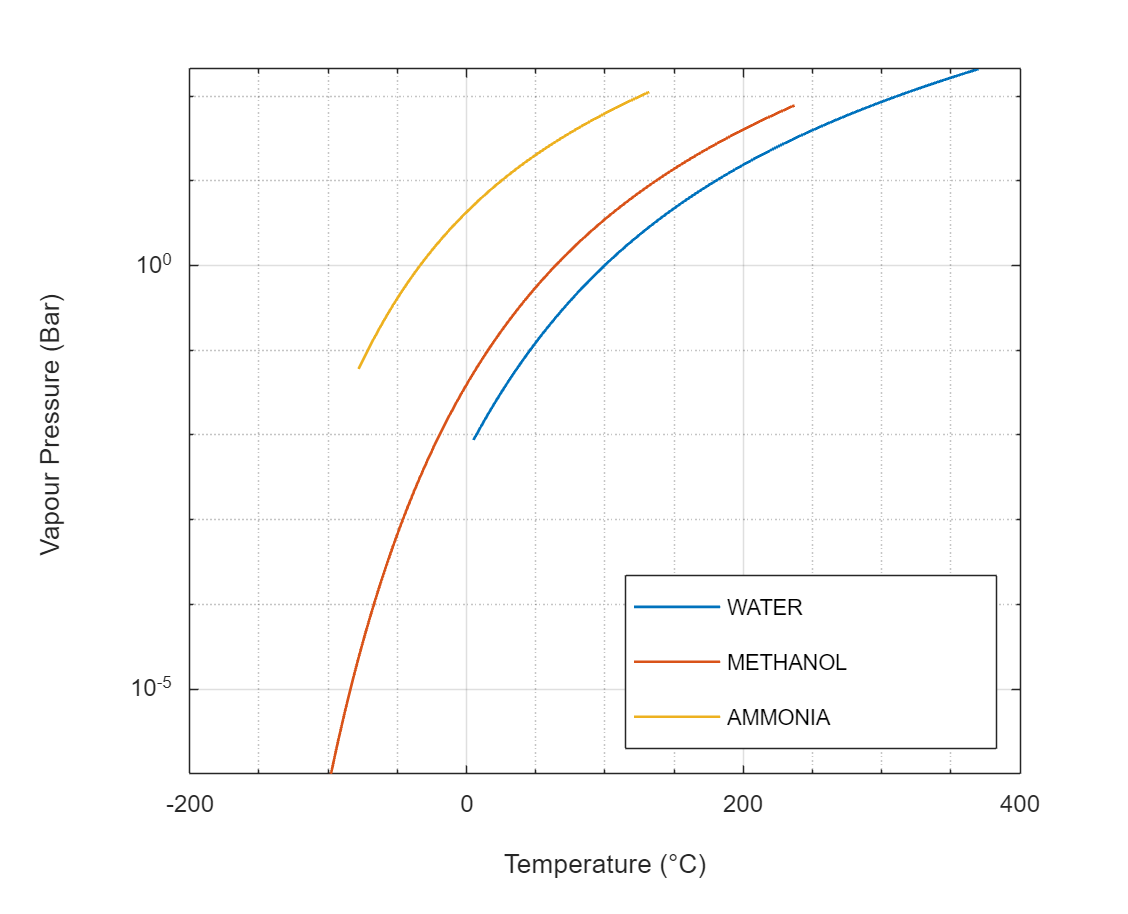

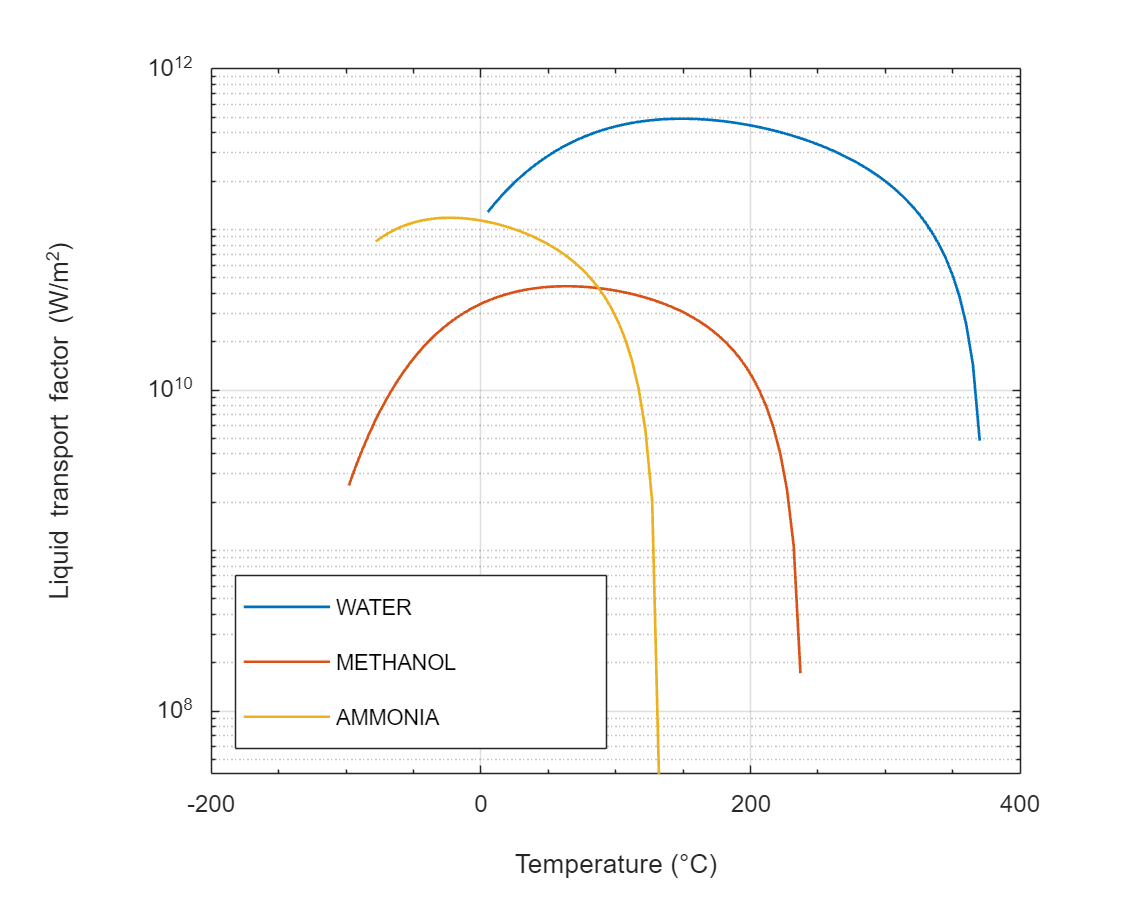

if Fluid2 ~= "0"
    clearvars -except Fluid1 Fluid2 Fluid3 Fluid4 Fluid5 Fluid6 Fluid7 Fluid8 Fluid9 Fluid10 WICK_TYPE Metal HP_Length COND_Length EVAP_Length HP_Angle OP_Temp HP_Diameter T_WALL OPRATING_POWER Mesh_material N_WRAPS MESH_NUMBER WICK_K gap_mult SINTER_D MAND Contact_Angle GRAVITY Rn sf D_WIRE
A_1_1_0b_DATA_EXTRACTION
B_1_1_0b_VARIABLE_DEFINITION
C_1_1_0b_CALCULATIONS
G1_1_1_0b_CAP_LIMIT
G2_1_1_0b_VAPOUR_PRESS
G3_1_1_0b_MERIT
% G4_1_1_0b_PROPERTY_DATA_CHECK
end

*SAVE OUTPUTS, Uncoment to save all graphs as .png*

% z4_SAVE

## Version Control

see zz_versioncontrol